%Experiment 1: Diode-Connected Transitor Characteristics
clear
clf
load('Experiment 1/IinVout/Vout.mat')
load('Experiment 1/IinVout/Iin.mat')
semilogy(Vout, Iin, '.')
hold on
title("Experiment 1: Diode-Connected Transitor Characteristics")
xlabel("Voltage (V)")
ylabel("Current (A")
grid on
%plot(Iin,Vout,".")

%line of best fit
[first, last, mmax, bmax, Nmax]=linefit(Vout, log(Iin), 5e-4);
Is = exp(bmax);
Ut = 1/mmax

Ut = 0.0258


th_Vout = Ut*log((Iin)/Is);
%plot(Iin, th_Vout)
semilogy(th_Vout, Iin)


%Vin Iout
load('Experiment 1/VinIout/Vin.mat')
load('Experiment 1/VinIout/Iout.mat')
%plot(Vin, Iout,".")
semilogy(Vin, Iout, '.')

%line of best fit
[first2, last2, mmax2, bmax2, Nmax2]=linefit(Vin, log(Iout), 5e-4);
Is2 = exp(bmax2);
Ut2 = 1/mmax2

Ut2 = 0.0261

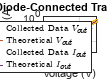


th_Iout = Is2*exp(Vin/Ut2);
th_Vout = Ut2*log((Iin)/Is2);
%plot(Iin, th_Vout)
semilogy(Vin, th_Iout)

legend("Collected Data $V_{out}$", "Theoretical $V_{out}$", "Collected Data $I_{out}$", "Theoretical $I_{out}$", "Interpreter", "latex")

hold off

%Experiment 1: 
clf
R = diff(Vout)./diff(Iin)

R = 1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0009    0.0011    0.0017    0.0021    0.0032    0.0040    0.0062    0.0077    0.0113    0.0157    0.0205    0.0321    0.0397    0.0620    0.0766    0.1197    0.1478    0.2311    0.2854    0.4461    0.5510    0.8613    1.0638    1.6630    2.2593


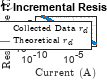

loglog(Iin(2:end), R, '.')
hold on
title("Experiment 1: Incremental Resistance vs Current")
xlabel("Current (A)", "Interpreter", "latex")
ylabel("Resistance ($\Omega$)", "Interpreter", "latex")
grid on

% line of best fit
th_R = Ut./Iin; % = dv/dI
loglog(Iin, th_R)

legend("Collected Data $r_{d}$", "Theoretical $r_{d}$", "Interpreter", "latex")

clear
clf
load('Experiment 2/100kohmnew/Vout.mat')
load('Experiment 2/100kohmnew/Vin.mat')
load('Experiment 2/100kohmnew/Iout.mat')
Vin_100k = Vin

Vin_100k =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


Vout_100k = Vout

Vout_100k =     0.0070    0.0580    0.1080    0.1580    0.2080    0.2570    0.3080    0.3570    0.4050    0.4480    0.4770    0.4960    0.5080    0.5175    0.5250    0.5290    0.5340    0.5380    0.5410    0.5450    0.5471    0.5500    0.5530    0.5546    0.5566    0.5589    0.5600    0.5620    0.5631    0.5650    0.5660    0.5680    0.5690    0.5700    0.5710    0.5721    0.5731    0.5750    0.5760    0.5770    0.5771    0.5780    0.5790    0.5800    0.5810    0.5820    0.5830    0.5831    0.5840    0.5850


Iout_100k = Iout

Iout_100k = 1.0e-04 *

   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0010    0.0031    0.0063    0.0101    0.0143    0.0186    0.0233    0.0278    0.0325    0.0371    0.0419    0.0466    0.0513    0.0561    0.0609    0.0658    0.0706    0.0755    0.0803    0.0851    0.0900    0.0949    0.0998    0.1047    0.1096    0.1145    0.1194    0.1243    0.1291    0.1340    0.1389    0.1438    0.1490    0.1539    0.1588    0.1638    0.1687    0.1737    0.1786    0.1835    0.1884


load('Experiment 2/10kohmnew/Vout.mat')
load('Experiment 2/10kohmnew/Vin.mat')
load('Experiment 2/10kohmnew/Iout.mat')
Vin_10k = Vin

Vin_10k =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


Vout_10k = Vout

Vout_10k =     0.0070    0.0580    0.1080    0.1580    0.2080    0.2570    0.3079    0.3570    0.4070    0.4570    0.5010    0.5330    0.5530    0.5670    0.5761    0.5840    0.5890    0.5930    0.5980    0.6010    0.6040    0.6070    0.6100    0.6120    0.6145    0.6161    0.6180    0.6200    0.6220    0.6231    0.6250    0.6260    0.6280    0.6290    0.6300    0.6320    0.6330    0.6338    0.6350    0.6360    0.6370    0.6380    0.6390    0.6400    0.6408    0.6410    0.6420    0.6430    0.6440    0.6441


Iout_10k = Iout

Iout_10k = 1.0e-03 *

   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0007    0.0026    0.0056    0.0093    0.0134    0.0177    0.0222    0.0267    0.0313    0.0359    0.0406    0.0453    0.0501    0.0548    0.0596    0.0644    0.0692    0.0741    0.0789    0.0837    0.0886    0.0934    0.0983    0.1032    0.1080    0.1129    0.1178    0.1227    0.1275    0.1323    0.1372    0.1424    0.1473    0.1522    0.1571    0.1620    0.1669    0.1719    0.1768    0.1817


load('Experiment 2/1kohmnew/Vout.mat')
load('Experiment 2/1kohmnew/Vin.mat')
load('Experiment 2/1kohmnew/Iout.mat')
Vin_1k = Vin

Vin_1k =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


Vout_1k = Vout

Vout_1k =     0.0070    0.0578    0.1080    0.1578    0.2080    0.2570    0.3080    0.3570    0.4070    0.4580    0.5070    0.5530    0.5885    0.6090    0.6240    0.6340    0.6420    0.6470    0.6520    0.6560    0.6600    0.6631    0.6660    0.6690    0.6720    0.6740    0.6760    0.6780    0.6800    0.6810    0.6830    0.6847    0.6860    0.6871    0.6890    0.6900    0.6910    0.6921    0.6932    0.6950    0.6960    0.6970    0.6977    0.6990    0.6999    0.7000    0.7010    0.7020    0.7030    0.7040


Iout_1k = Iout

Iout_1k =    -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0016    0.0016    0.0017    0.0017    0.0018



Ut = 0.025

Ut = 0.0250

Ion = Ut/100000

Ion = 2.5000e-07

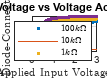


plot(Vin_100k, Vout_100k, '.');
hold on;
grid on;
plot(Vin_100k, Vin_100k .* (Ion./(Ion+Iout_100k)))
plot(Vin_10k, Vout_10k, '.');
plot(Vin_1k, Vout_1k, '.');
legend("$100k\Omega$", "$10k\Omega$", "$1k\Omega$", "Interpreter","latex")
title("Experiment 2: Applied Input Voltage vs Voltage Across Diode-Connected Transistor")
xlabel("Applied Input Voltage ($V$)", "Interpreter", "latex")
ylabel("Voltage Across Diode-Connected Transistor ($V$)", "Interpreter", "latex")
hold off;

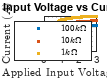


semilogy(Vin_100k, Iout_100k, '.');
hold on;
grid on;
semilogy(Vin_10k,` Iout_10k, '.');
semilogy(Vin_1k, Iout_1k, '.');
legend("$100k\Omega$", "$10k\Omega$", "$1k\Omega$", "Interpreter","latex")
title("Experiment 2: Applied Input Voltage vs Current Flowing into the Circuit")
xlabel("Applied Input Voltage ($V$)", "Interpreter", "latex")
ylabel("Current ($A$)", "Interpreter", "latex")
hold off;

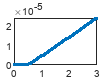


plot(Vin_100k, Iout_100k, '.');

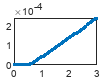

plot(Vin_10k, Iout_10k, '.');

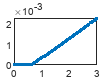

plot(Vin_1k, Iout_1k, '.');